# Create and Customize Mesh-Contour Plots

`meshc` creates a three-dimensional surface plot that has solid edge colors and no face colors accompanied by a 2-D contour map on the $x-y$ plane. The function plots the values in a matrix `Z` as heights above a grid in the *x*-*y* plane. 

### Generate Membrane Matrix

A 2-D array is necessary for plotting a mesh surface. Specify a matrix surface matrix Z derived from the peaks command. 

Z = peaks(50);

### Basic Mesh-Contour Plot

Mesh plots are three-dimensional plots that look like a fish-net shaped lattice of horizontal and vertical lines that are draped over a surface. 

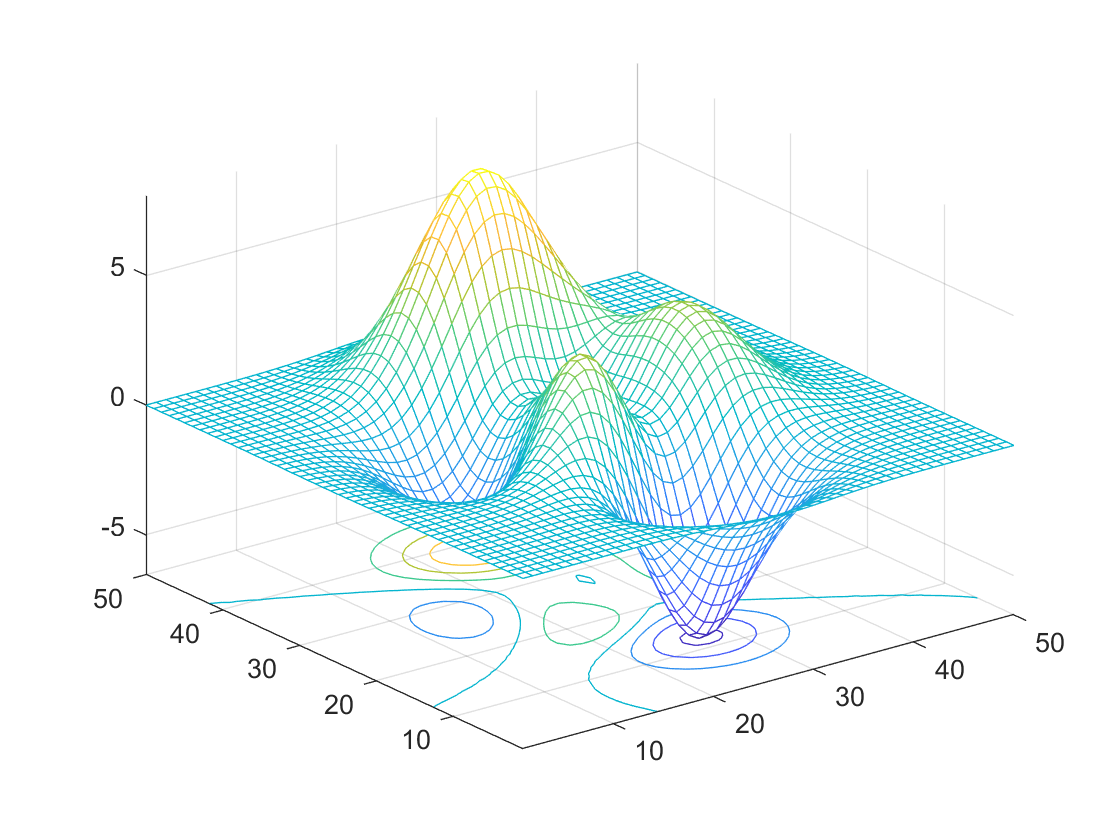

meshc(Z);

## Customizing Mesh Plots

### Modify the Contour Plot Appearance

To modify appearances specific to either the contour plot or the surface plot, you must assign the graphics array containing the surface and contour objects to the variable mc. From this variable, properties influencing the line appearance such as *LineWidth *or *EdgeColor *can be specified using dot notation referencing. The object for the plot, `ms`, has a first section containing these properties for the surface, and a second for the contour. Chose which plot to modify the properties of by brace notation.

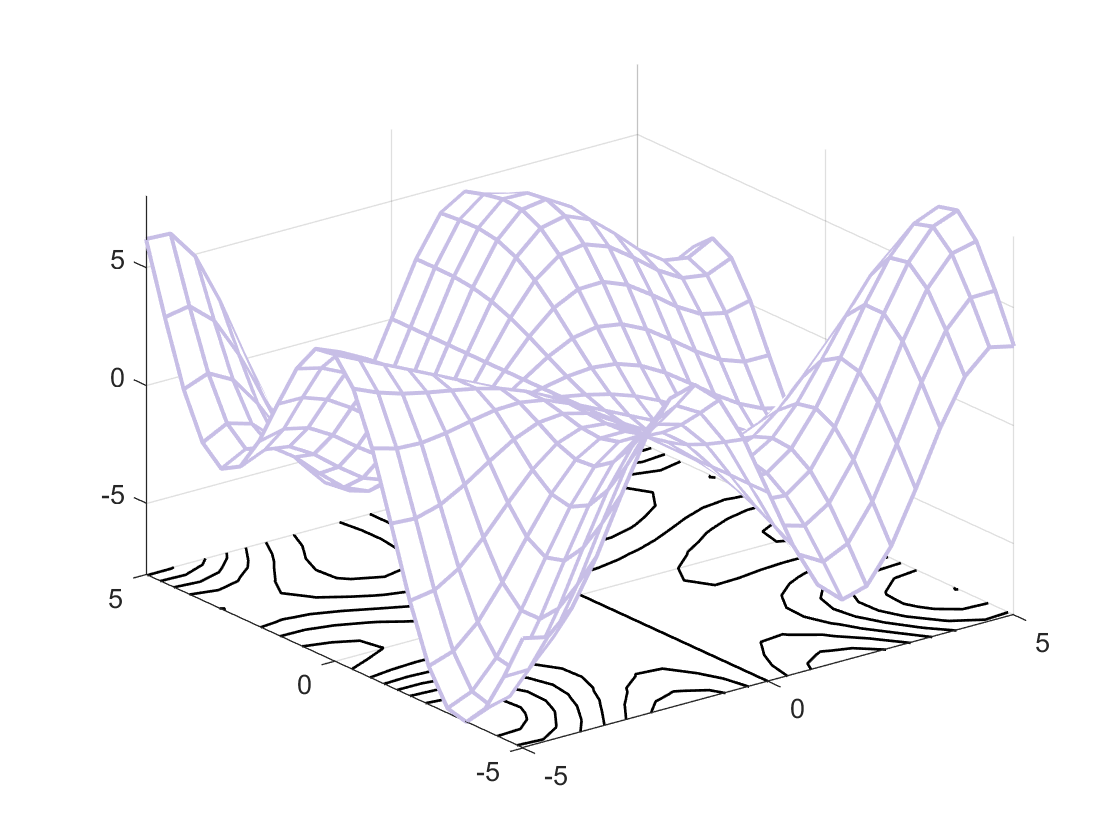

[X,Y] = meshgrid(-5:.5:5);
Z = Y.*sin(X) - X.*cos(Y);

mc = meshc(X,Y,Z);
mc(2).EdgeColor = 'k';                  % Specify contour line color
mc(2).LineWidth = 1;            % Specify contour line width
mc(2).LineStyle = '-';                  % Specify contour line style
mc(1).EdgeColor = [0.7812, 0.7461, 0.9023];              % Specify surface line color using an RGB set
mc(1).LineWidth = 1.5;            % Specify surface line width

### Specify the Location of the Contour Plot

The contour lines appear at the minimum *z*-level by default, but you can change the location by setting the `ZLocation` property. Display the `peaks` data set as a mesh plot with the contours at the minimum *z*-level. Specify a return argument when you call the `meshc` function so that you can access the `Contour` object. Set the *ZLocation *property to plot the x-y contour plane at the hieghest z-value.

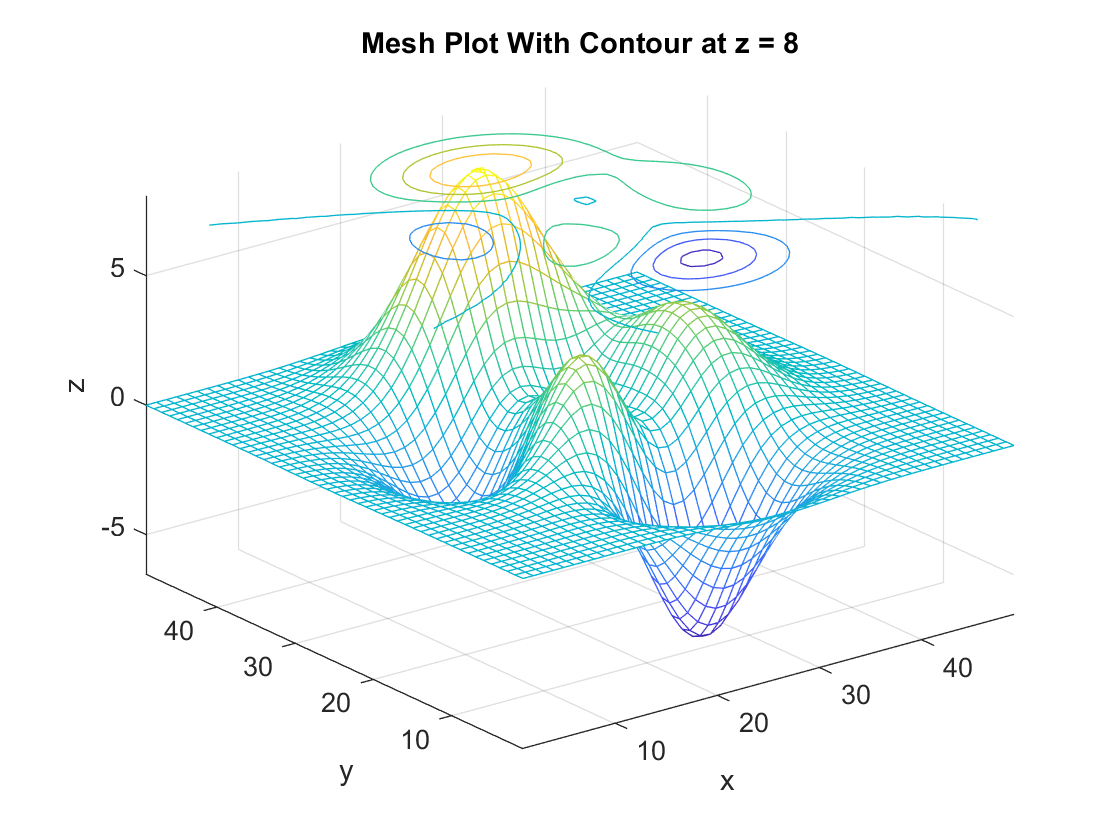

Z = peaks;
sc = meshc(Z);
sc(2).ZLocation = 'zmax';

title('Mesh Plot With Contour at z = 8')
xlabel('x')
ylabel('y')
zlabel('z')

## **Additional Information**

### **Get All Meshc Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a meshc, uncomment the following code

% get(ms)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[meshc](https://www.mathworks.com/help/matlab/ref/meshc.html)